# Bifurcation diagram for the lollipop graph

This code draws the bifurcation diagram much like the the one from Figure 3.3 of Goodman, R. H. [NLS bifurcations on the bowtie combinatorial graph and the dumbbell metric graph](http://doi.org/10.3934/dcds.2019093) but this one will use a Chebyshev discretization instead of uniform. 

We use 

- Six programs from the directory `source/continuation` which an end-user may simply run themselves

- Two programs from `source/examples` which an end-user could copy in creating their own project

Note how each of the routines outputs one or more identifiers that are used to call later routines that continue from points on the computed branches

## Construct the quantum graph and find the first few eigenfunctions

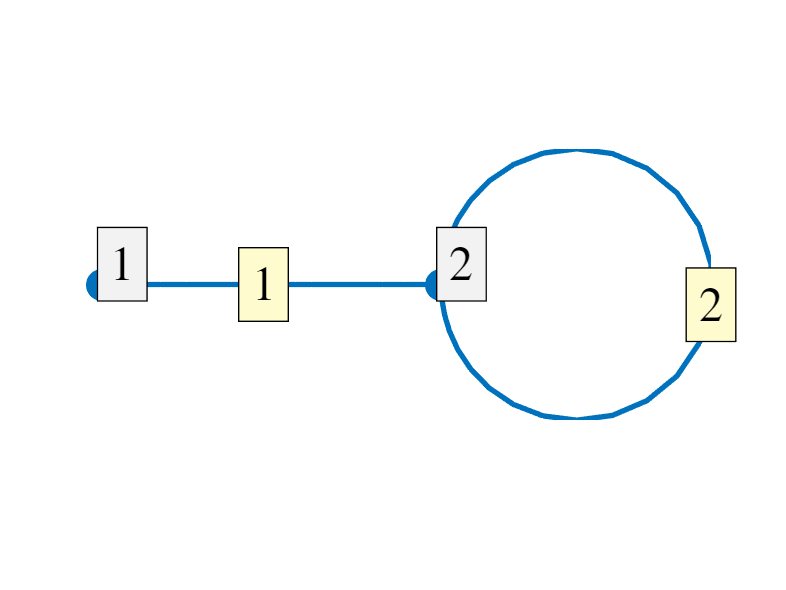

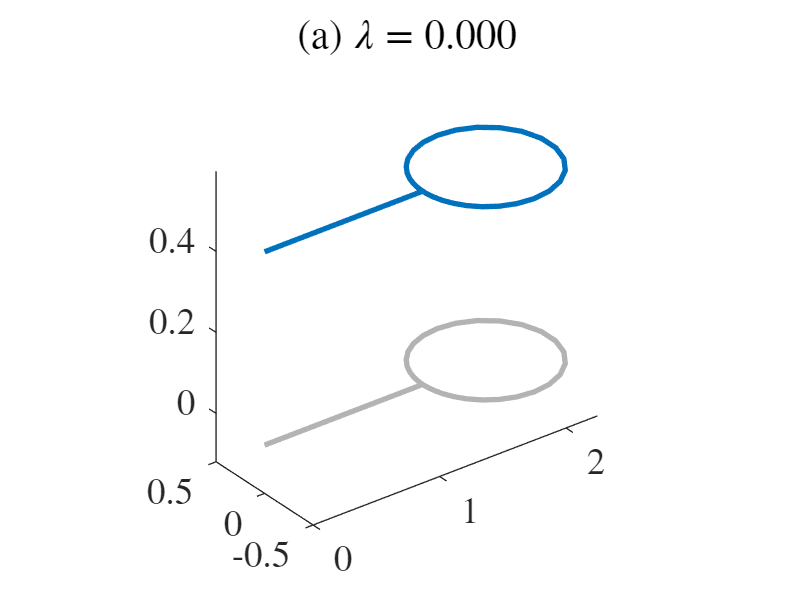

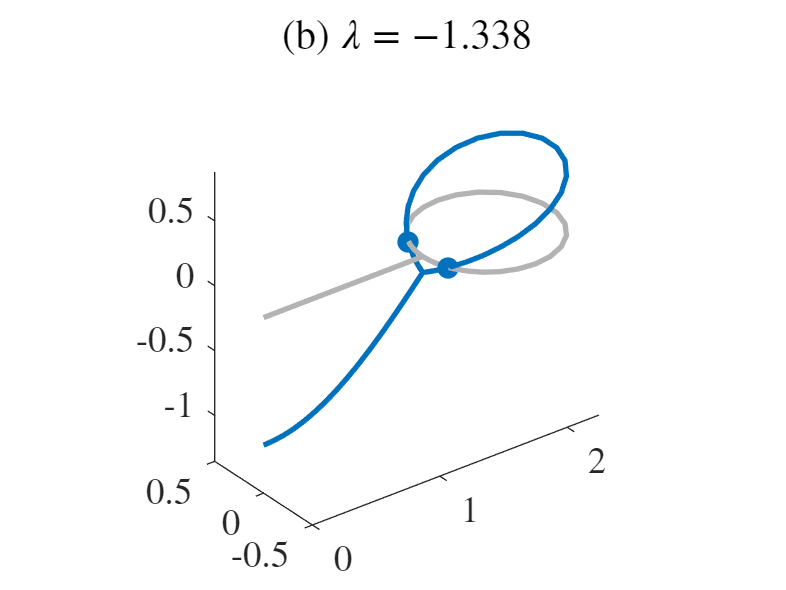

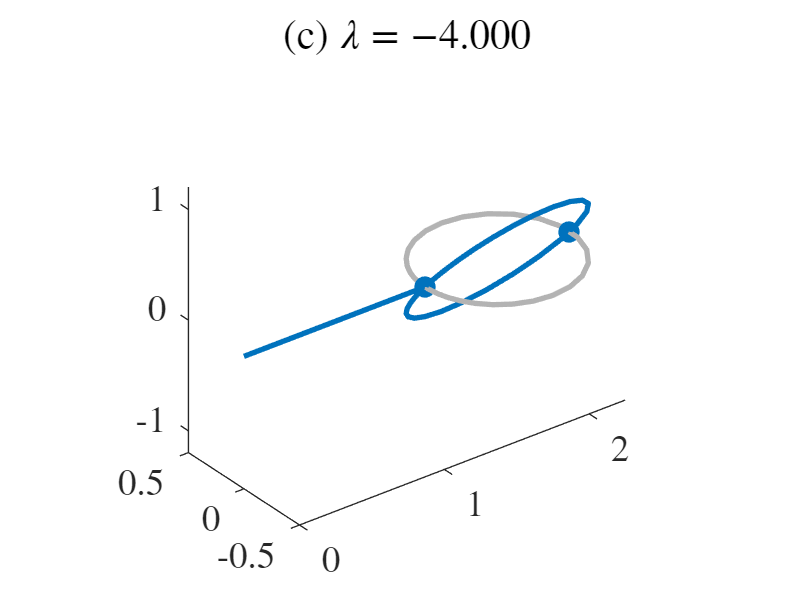

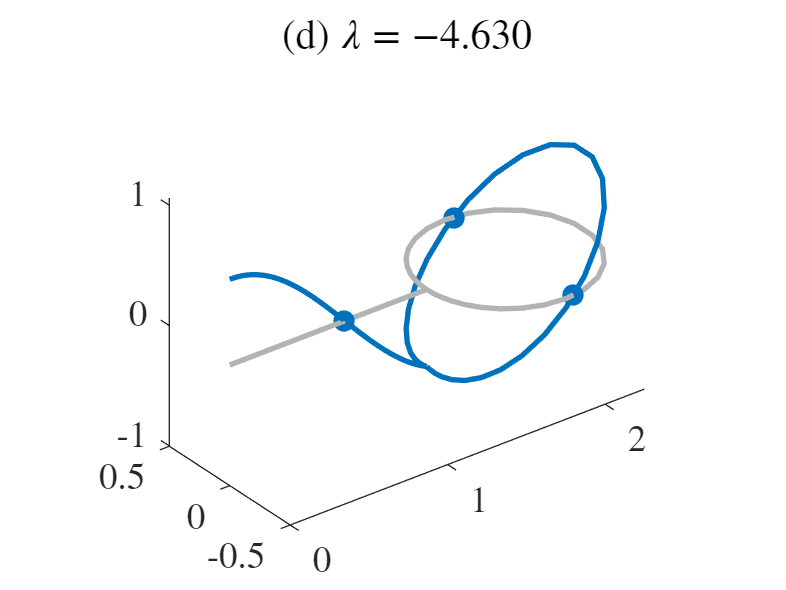

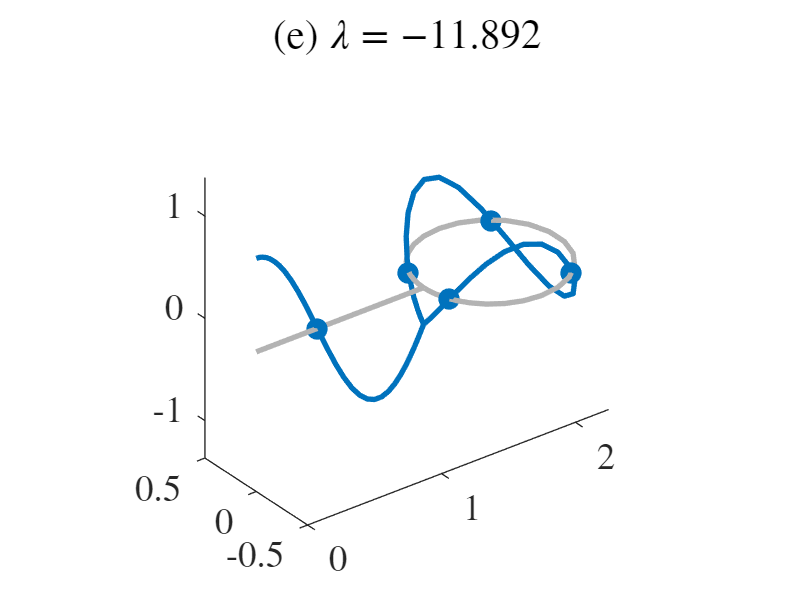

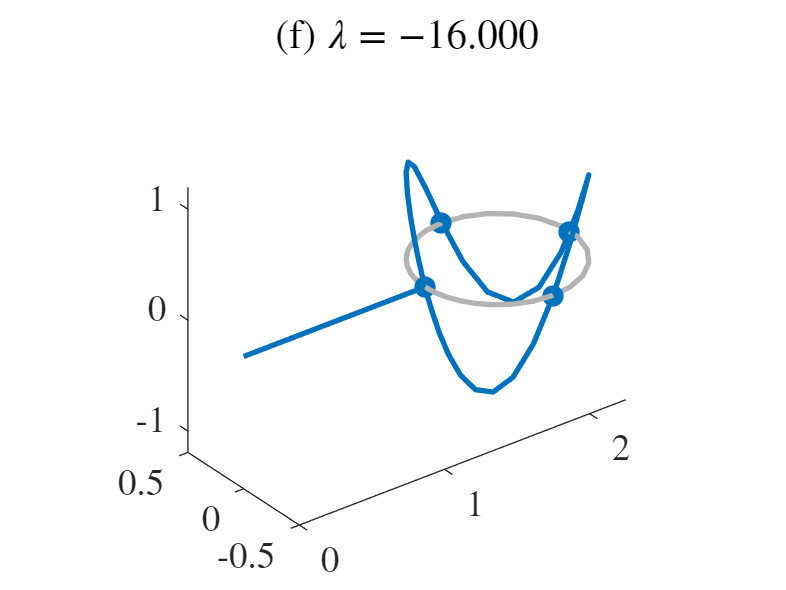

Saved to directory data\multibell\001.
Run number is 1.


close all
tag='multibell';
Phi = quantumGraphFromTemplate(tag,'LVec',[1.25,pi],'discretization','Chebyshev','nx',32,'nbells',1);

nToPlot=6;
nDoubles=0;
nTriples=0;
diagramNumber=eigenfunctionsSaveData(Phi,tag,nToPlot,nDoubles,nTriples);

## Compute a branch that is a continuation of the ground state eigenfunction

- The function `continuerSet` acts like the MATLAB functions `odeset` and `optimset.` It sets a number of options that are used by the continuation programs

- The function `continueFromEig` continues a branch from the linear limit of an eigenfunction computed in the previous step

options=continuerSet([],'LambdaThresh',-15,'NThresh',20,'plotFlag',false);
eigNumber=1;
[bn1,bl1]=continueFromEig(tag,diagramNumber,eigNumber,options);

N threshold crossed.
Branch number 1.
Data saved to directory data\multibell\001\branch001.
Branching Bifurcation at solution number 11.
Branching Bifurcation at solution number 25.
Branching Bifurcation at solution number 28.
Branching Bifurcation at solution number 30.


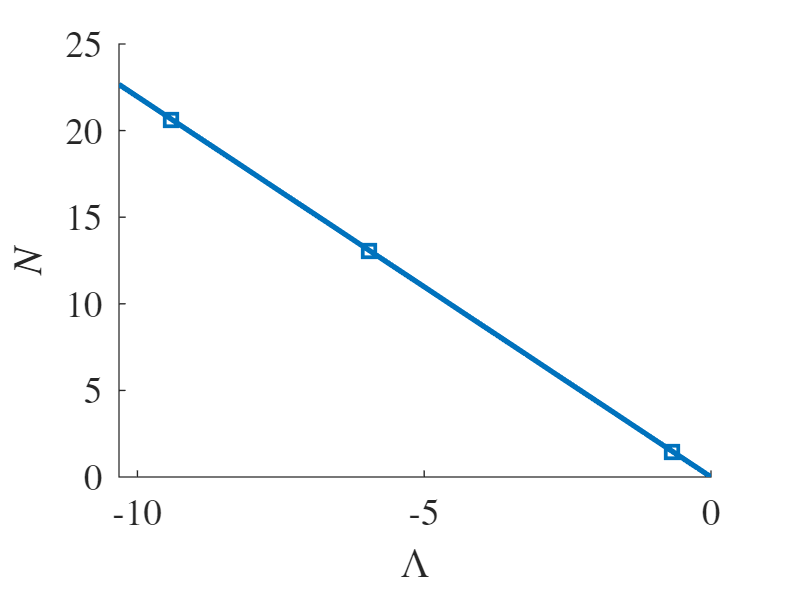

bifurcationDiagram(tag,diagramNumber)

## Compute some branches that bifurcate from this first branch

[bn2,bl2]=continueFromBranchPoint(tag,diagramNumber,bn1,bl1(1),1,options);

Lambda threshold crossed.
Branch number 2.
Data saved to directory data\multibell\001\branch002.
No branching bifurcations found.


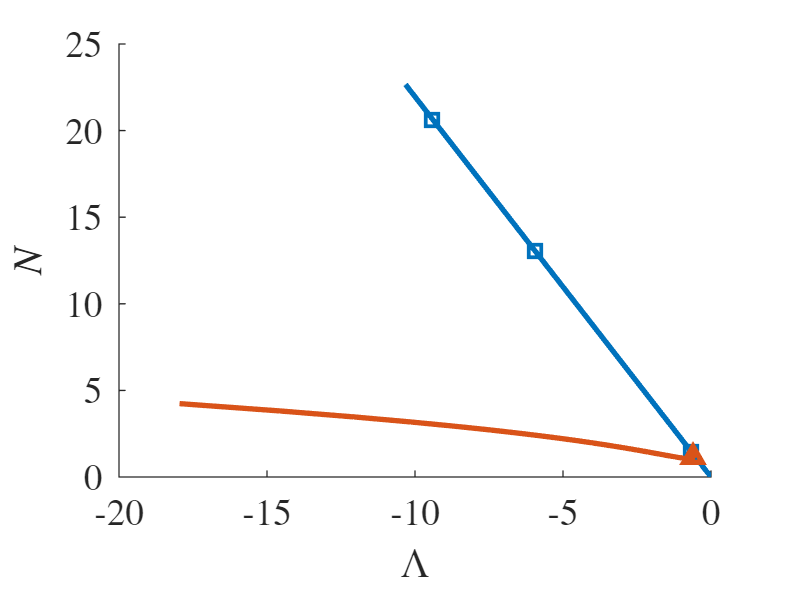

bifurcationDiagram(tag,diagramNumber)

[bn3,bl3]=continueFromBranchPoint(tag,diagramNumber,bn1,bl1(1),-1,options);

Lambda threshold crossed.
Branch number 3.
Data saved to directory data\multibell\001\branch003.
Branching Bifurcation at solution number 48.


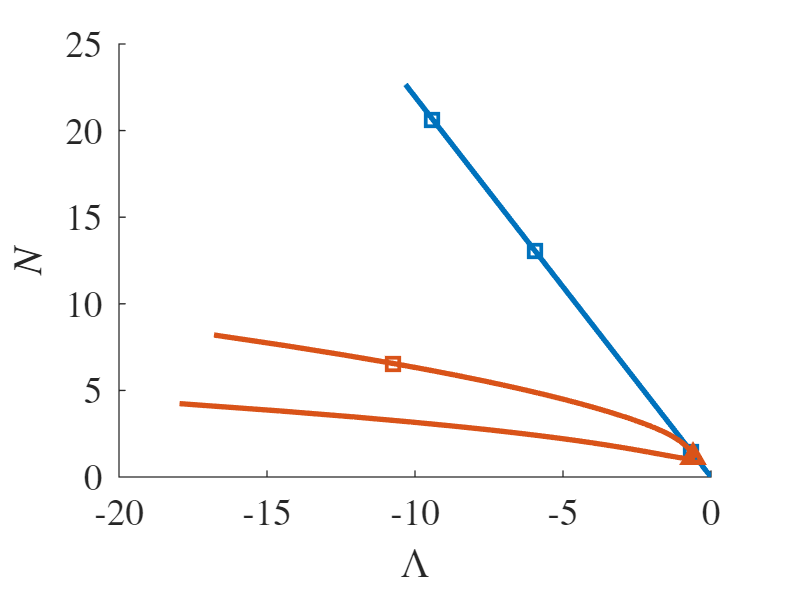

bifurcationDiagram(tag,diagramNumber)

[bn4,bl4]=continueFromBranchPoint(tag,diagramNumber,bn1,bl1(2),1,options);

Lambda threshold crossed.
Branch number 4.
Data saved to directory data\multibell\001\branch004.
No branching bifurcations found.


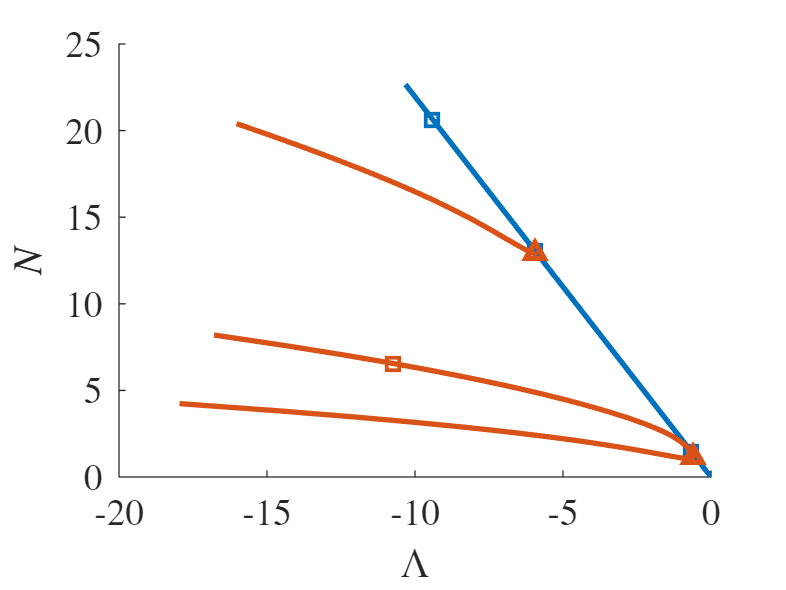

bifurcationDiagram(tag,diagramNumber)

[bn5,bl5]=continueFromBranchPoint(tag,diagramNumber,bn1,bl1(2),-1,options);

Lambda threshold crossed.
Branch number 5.
Data saved to directory data\multibell\001\branch005.
No branching bifurcations found.


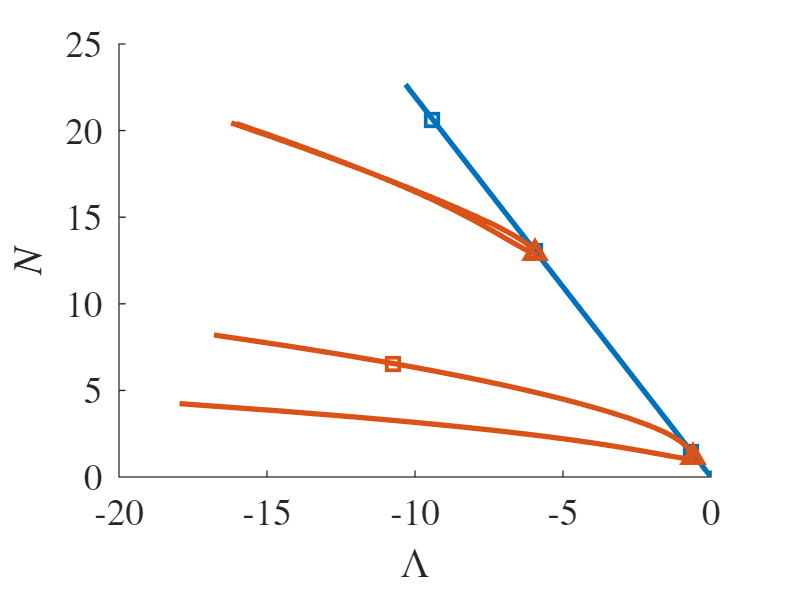

bifurcationDiagram(tag,diagramNumber)

[bn6,bl6]=continueFromBranchPoint(tag,diagramNumber,bn3,bl3(1),1,options);

Lambda threshold crossed.
Branch number 7.
Data saved to directory data\multibell\001\branch007.
No branching bifurcations found.


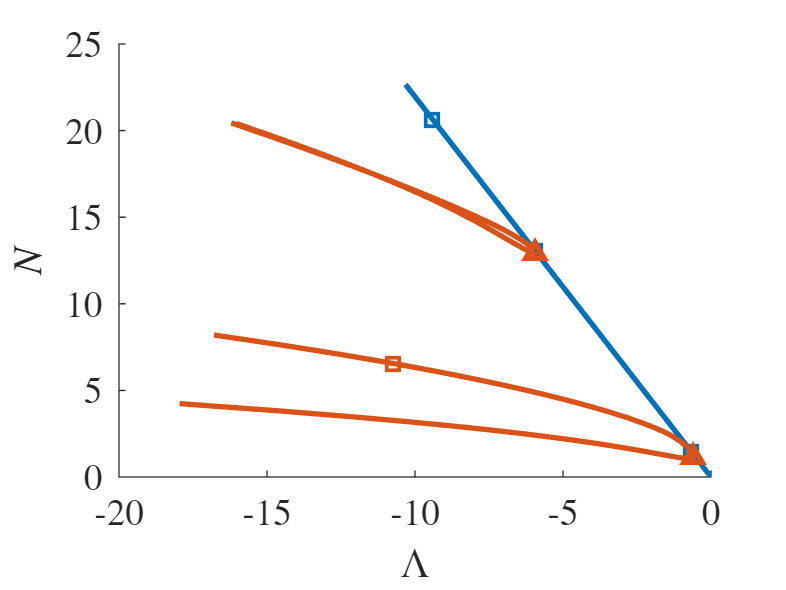

bifurcationDiagram(tag,diagramNumber) % Why isn't it bifurcating off the square?

## Plot some solutions

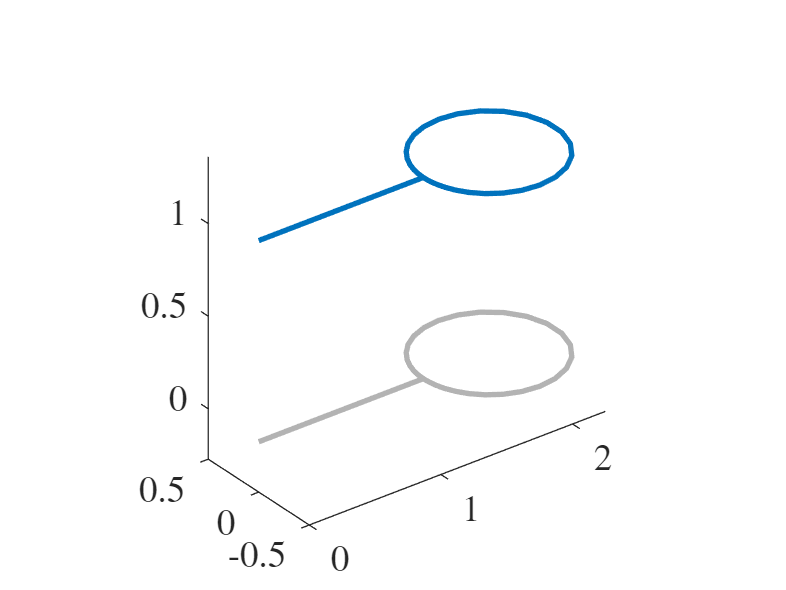

plotSolution(tag,diagramNumber,bn1,18)

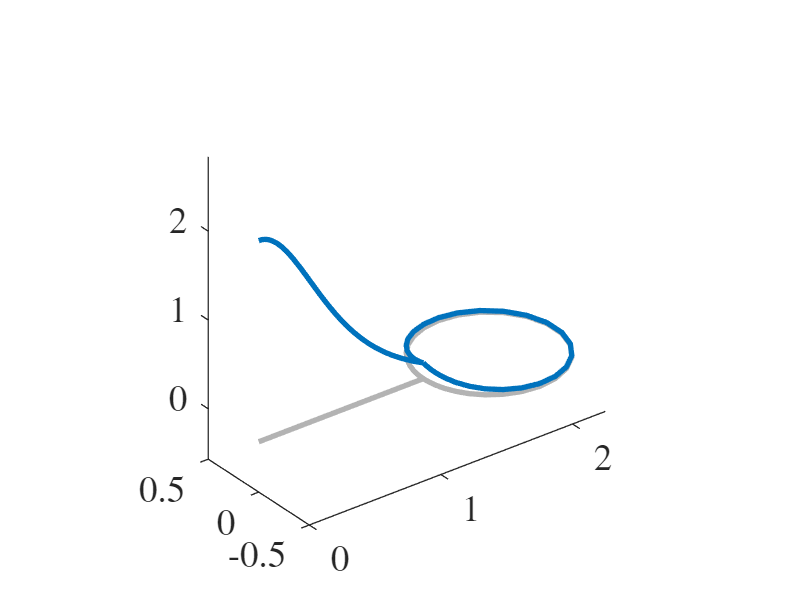

plotSolution(tag,diagramNumber,bn2,46)

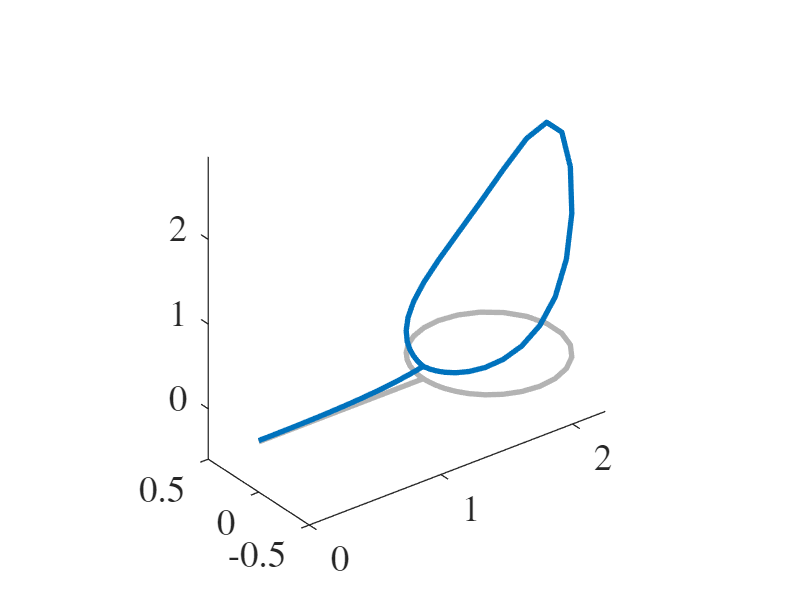

plotSolution(tag,diagramNumber,bn3,42)

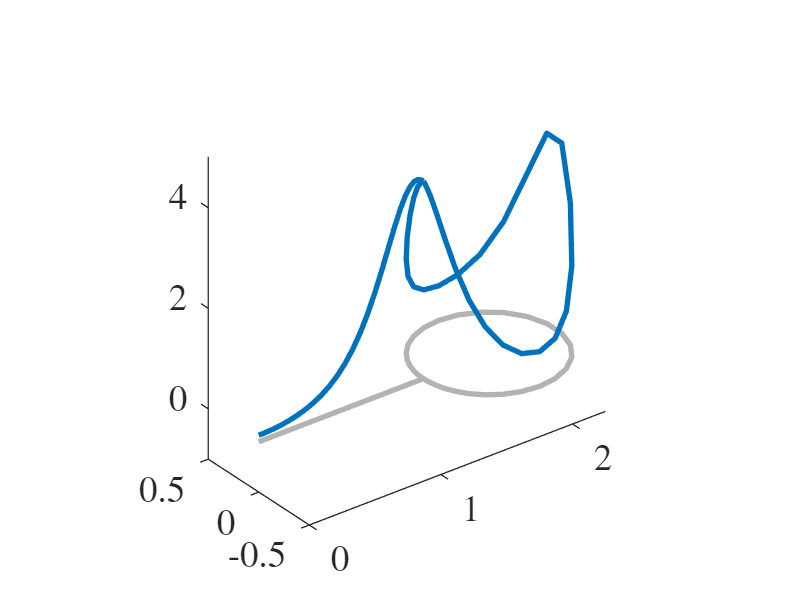

plotSolution(tag,diagramNumber,bn4,'last')

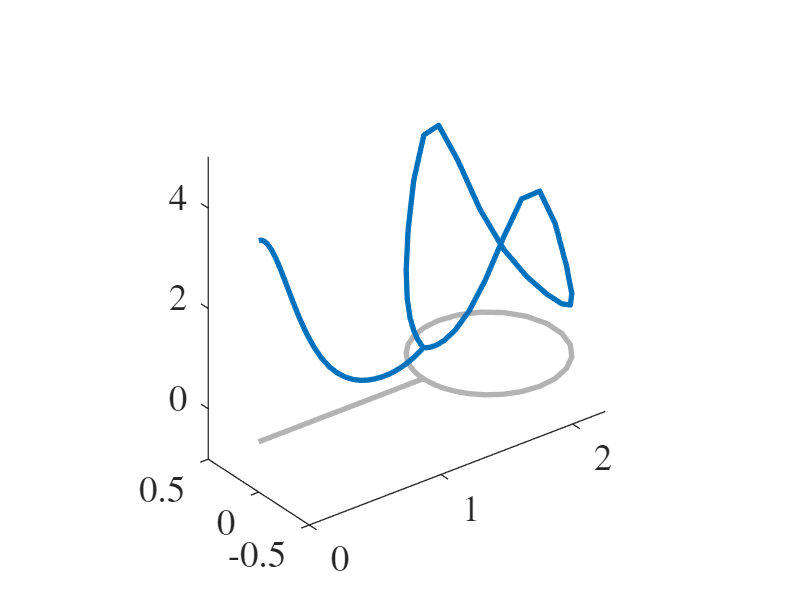

plotSolution(tag,diagramNumber,bn5,'last')

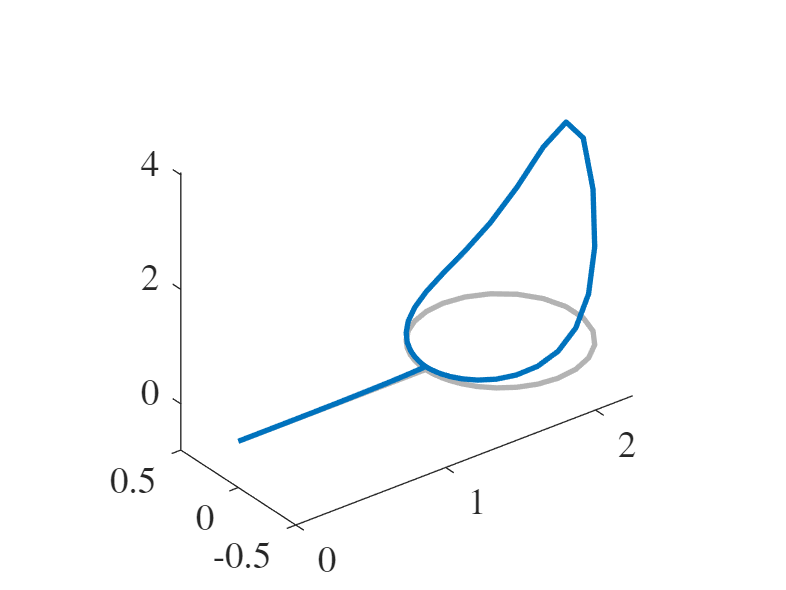

plotSolution(tag,diagramNumber,bn6,14)